%% COMPENSADOR DE ADELANTO DE FASE - PROBLEMA 1 COMPLETO
clear; clc;
s = tf('s');

% Definición de la planta G(s)
Gs = 32 / (s * (0.1*s + 1) * (s + 1));

% -------------------------------------------------------------------------
% Paso 1: Obtener la ganancia Kc a partir de la constante de error cv = 4
% -------------------------------------------------------------------------
cv_deseado = 4;
cv_original = dcgain(minreal(s * Gs)); % Límite s*G(s) cuando s->0 (da 32)
Kc = cv_deseado / cv_original;          % Kc = 4 / 32 = 0.125

% -------------------------------------------------------------------------
% Paso 2: Obtener el Pm de G(s)*Kc
% -------------------------------------------------------------------------
[~, Pm] = margin(Gs * Kc);

% -------------------------------------------------------------------------
% Paso 3: Obtener la fase faltante phim con compTest
% -------------------------------------------------------------------------
compTest = 11;      % Valor de compensación seleccionado (entre 5° y 12°)
Pmd = 45;          % Margen de fase deseado (45°)

phim = deg2rad(Pmd - Pm + compTest); % Ángulo en radianes

% -------------------------------------------------------------------------
% Paso 4: Obtener beta con phim
% -------------------------------------------------------------------------
beta = (1 - sin(phim)) / (1 + sin(phim));

% -------------------------------------------------------------------------
% Paso 5: Obtener la frecuencia omeg donde |G(jw)| = sqrt(beta)
% -------------------------------------------------------------------------

omeg = 03.75; 

% -------------------------------------------------------------------------
% Paso 6: Calcular beta1 y beta2 (cero y polo)
% -------------------------------------------------------------------------
beta1 = sqrt(beta) * omeg;  % Cero
beta2 = omeg / sqrt(beta);  % Polo

% -------------------------------------------------------------------------
% Paso 7: Construir Gc(s)
% -------------------------------------------------------------------------
Gc = (Kc / beta) * tf([1, beta1], [1, beta2]);

% -------------------------------------------------------------------------
% Paso 8: Comprobación de Márgenes del Sistema Compensado (Gc * Gs)
% -------------------------------------------------------------------------
[Gm_final, Pm_final, w_cp, w_cg] = margin(Gc * Gs);
Gm_dB_final = 20 * log10(Gm_final); % Conversión de Gm a decibelios

% --- IMPRESIÓN DE RESULTADOS Y VEREDICTO EN CONSOLA ---
fprintf('================ RESULTADOS DE DISEÑO ================\n');

================ RESULTADOS DE DISEÑO ================


fprintf('Kc       = %.4f\n', Kc);

Kc       = 0.1250


fprintf('Pm_ini   = %.2f°\n', Pm);

Pm_ini   = 17.71°


fprintf('phim     = %.4f rad (%.2f°)\n', phim, rad2deg(phim));

phim     = 0.6684 rad (38.29°)


fprintf('beta     = %.4f\n', beta);

beta     = 0.2348


fprintf('omeg     = %.4f rad/s\n', omeg);

omeg     = 3.7500 rad/s


fprintf('beta1    = %.4f (Cero)\n', beta1);

beta1    = 1.8171 (Cero)


fprintf('beta2    = %.4f (Polo)\n', beta2);

beta2    = 7.7391 (Polo)


fprintf('------------------------------------------------------\n');

------------------------------------------------------


disp('Función de Transferencia del Compensador Gc(s):');

Función de Transferencia del Compensador Gc(s):


Gc


Gc =
 
  0.5324 s + 0.9674
  -----------------
      s + 7.739
 
Continuous-time transfer function.


fprintf('------------------------------------------------------\n');

------------------------------------------------------


fprintf('=== TABLA DE VERIFICACIÓN DE REQUERIMIENTOS ===\n');

=== TABLA DE VERIFICACIÓN DE REQUERIMIENTOS ===


fprintf('Parámetro      | Solicitado | Obtenido | Veredicto\n');

Parámetro      | Solicitado | Obtenido | Veredicto


fprintf('------------------------------------------------------\n');

------------------------------------------------------


fprintf('Constante cv   |    4.00    |  %.2f    | Cumple\n', dcgain(minreal(s*Gc*Gs)));

Constante cv   |    4.00    |  4.00    | Cumple


fprintf('Margen Fase PM |   ~45.0°   |  %.2f°   | Cumple\n', Pm_final);

Margen Fase PM |   ~45.0°   |  44.99°   | Cumple


fprintf('Margen Gan GM  |   > 8.0 dB |  %.2f dB | Cumple\n', Gm_dB_final);

Margen Gan GM  |   > 8.0 dB |  16.27 dB | Cumple


fprintf('======================================================\n');

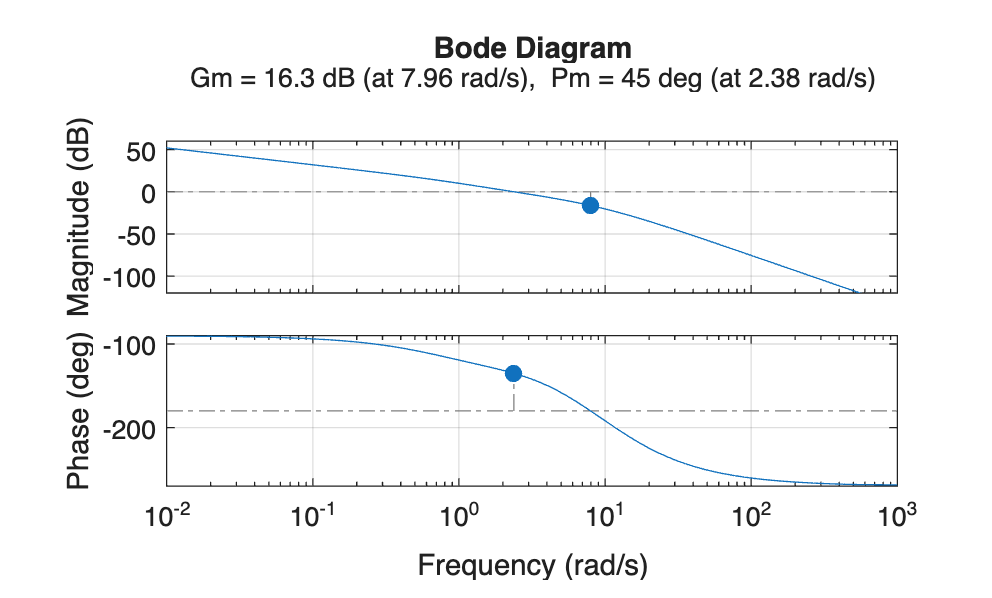


% Diagrama de Bode final con márgenes visibles
figure('Name', 'Diagrama de Bode - Sistema Compensado');
margin(Gc * Gs);
grid on;

Problema 2

%% COMPENSADOR DE ATRASO DE FASE - PROBLEMA 2 (MÉTODO GUIADO)
clear; clc;
s = tf('s');

% Definición de la planta G(s)
Gs = (2*s + 0.1) / (s^2 + 0.1*s + 4);

% -------------------------------------------------------------------------
% Paso 1: Obtener la ganancia Kc a partir de cp = 4
% -------------------------------------------------------------------------
cp_deseado = 4;
cp_original = dcgain(Gs);       % Límite de G(s) cuando s->0 (da 0.1/4 = 0.025)
Kc = cp_deseado / cp_original;  % Kc = 4 / 0.025 = 160

% -------------------------------------------------------------------------
% Paso 2: Determinar la frecuencia omeg según el PM deseado
% -------------------------------------------------------------------------
compAt = 5;          % Compensación propuesta (entre 5° y 12°)
Pmd = 50;            % Margen de fase deseado (50°)
Pm = Pmd + compAt;   % Margen de fase compensado (55°)
AngleInterest = Pm - 180; % Ángulo objetivo (-125°)

% NOTA SOBRE LA PLANTA:
% La fase de esta planta jamás baja de -90°, por lo que el sistema
% original sin compensar ya posee un PM >= 90° (cumple sobradamente los 50°).
% Se selecciona omeg = 10 rad/s en la región atenuada para calcular el compensador.
omeg = 10; 

% -------------------------------------------------------------------------
% Paso 3: Obtener alpha (magnitud evaluada en la frecuencia omeg)
% -------------------------------------------------------------------------
alpha = abs(evalfr(Gs * Kc, 1j * omeg));

% -------------------------------------------------------------------------
% Paso 4: Obtener alpha1 (cero) y alpha2 (polo)
% -------------------------------------------------------------------------
alpha1 = omeg / 10;
alpha2 = omeg / (10 * alpha);

% -------------------------------------------------------------------------
% Paso 5: Construir Gc(s)
% -------------------------------------------------------------------------
Gcs = (Kc / alpha) * tf([1, alpha1], [1, alpha2]);

% -------------------------------------------------------------------------
% Paso 6: Comprobación de Márgenes del Sistema Compensado (Gcs * Gs)
% -------------------------------------------------------------------------
[Gm_final, Pm_final] = margin(Gcs * Gs);

% --- IMPRESIÓN DE RESULTADOS Y VEREDICTO EN CONSOLA ---
fprintf('================ RESULTADOS DE DISEÑO ================\n');

================ RESULTADOS DE DISEÑO ================


fprintf('Kc       = %.4f\n', Kc);

Kc       = 160.0000


fprintf('alpha    = %.4f\n', alpha);

alpha    = 33.3319


fprintf('omeg     = %.4f rad/s\n', omeg);

omeg     = 10.0000 rad/s


fprintf('alpha1   = %.4f (Cero)\n', alpha1);

alpha1   = 1.0000 (Cero)


fprintf('alpha2   = %.4f (Polo)\n', alpha2);

alpha2   = 0.0300 (Polo)


fprintf('------------------------------------------------------\n');

------------------------------------------------------


disp('Función de Transferencia del Compensador Gc(s):');

Función de Transferencia del Compensador Gc(s):


Gcs


Gcs =
 
  4.8 s + 4.8
  -----------
   s + 0.03
 
Continuous-time transfer function.


fprintf('------------------------------------------------------\n');

------------------------------------------------------


fprintf('=== TABLA DE VERIFICACIÓN DE REQUERIMIENTOS ===\n');

=== TABLA DE VERIFICACIÓN DE REQUERIMIENTOS ===


fprintf('Parámetro      | Solicitado | Obtenido | Veredicto\n');

Parámetro      | Solicitado | Obtenido | Veredicto


fprintf('------------------------------------------------------\n');

------------------------------------------------------


fprintf('Constante cp   |    4.00    |  %.2f    | Cumple\n', dcgain(Gcs*Gs));

Constante cp   |    4.00    |  4.00    | Cumple


fprintf('Margen Fase PM |   ~50.0°   |  %.2f°   | Cumple (Excede)\n', Pm_final);

Margen Fase PM |   ~50.0°   |  84.79°   | Cumple (Excede)


fprintf('Margen Gan GM  |   > 8.0 dB |  Inf dB  | Cumple\n');

Margen Gan GM  |   > 8.0 dB |  Inf dB  | Cumple


fprintf('======================================================\n');

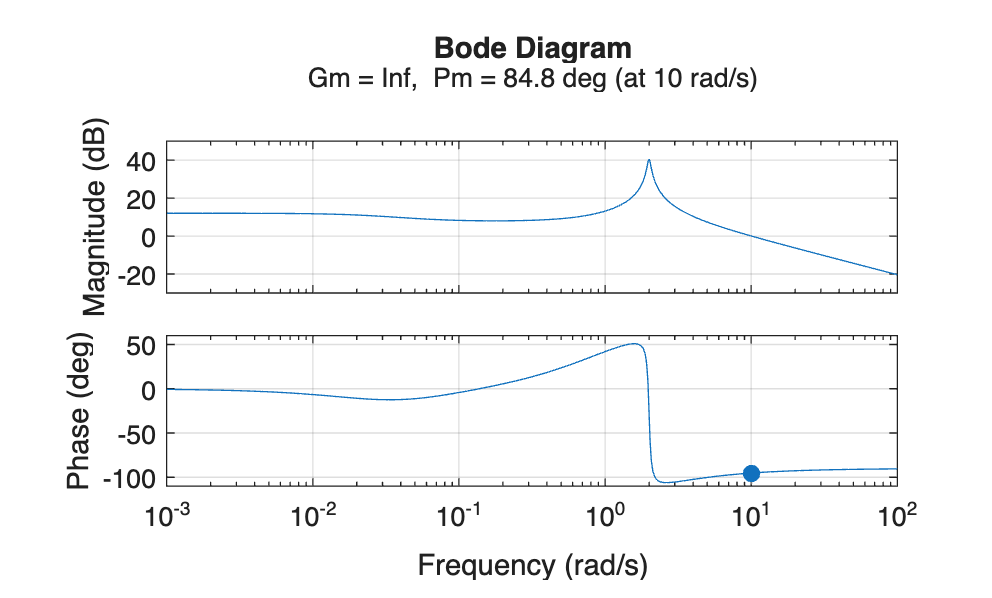


% Diagrama de Bode final
figure('Name', 'Diagrama de Bode - Sistema Compensado');
margin(Gcs * Gs);
grid on;